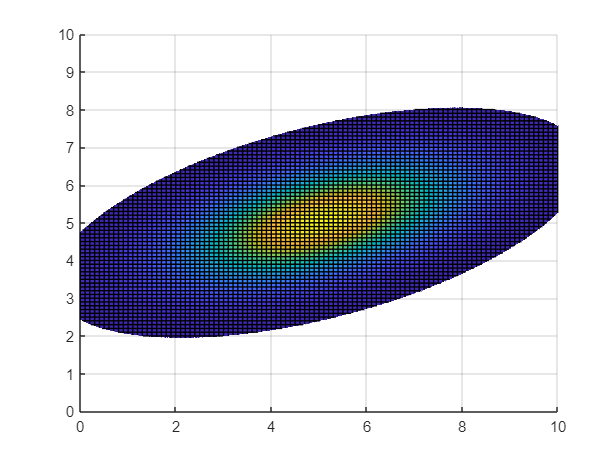

clear variables; close all; clc;
nx = 2;
mu = [5; 5]; % vettore colonna
sigma = randn(nx, nx);
sigma = sigma' * sigma;
[x1, x2] = meshgrid(0:0.1:10, 0:0.1:10);
Z = nan(size(x1));
for ii = 1 : length(x1)
    for jj = 1 : length(x2)
        Z(ii, jj) = mvnpdf([x1(ii, jj); x2(ii, jj)], mu, sigma);
    end
end
surf(x1, x2, Z)
zlim([0.001, 0.15])

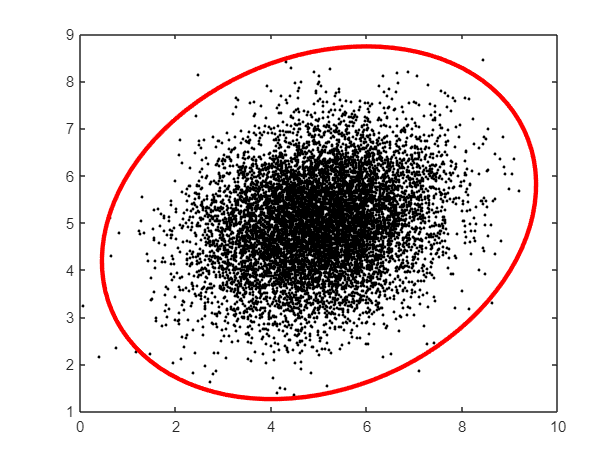

nx = 2;
mu = [5, 5]; % vettori riga!
sigma = randn(nx, nx);
points = mvnrnd(mu, sigma, 10000);
y = mvnpdf(points, mu, sigma);
plot(points(:, 1), points(:, 2), 'k.');
p = 0.999;
s = -2 * log(1 - p);
[V, D] = eig(sigma * s);
t = linspace(0, 2 * pi);
a = (V * sqrt(D)) * [cos(t(:))'; sin(t(:))'];
hold on;
plot(a(1, :) + mu(1), a(2, :) + mu(2), 'r', 'LineWidth', 3);

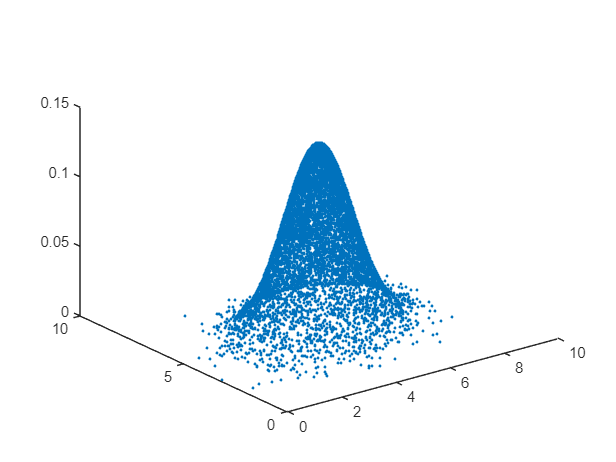

figure();
plot3(points(:, 1), points(:, 2), y, '.')